clc; clear; close all;

# 2D-FC solver for function over square domain

f = @(x, y) exp(x.^2 + y.^2)

f = function_handle with value:
    @(x,y)exp(x.^2+y.^2)



% data given in S-type patch
n = 200;
h = 1./(n-1);
D_mesh = linspace(0, 1, n)

D_mesh =          0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462


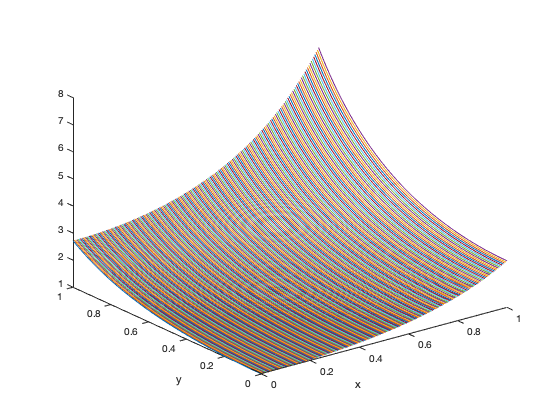

C = 27;
d = 10;

% load matrices for continuation
load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);


% functions on mesh
[X, Y] = meshgrid(D_mesh);
f_xy = f(X, Y);

% R - bounding box of extended function
[R_X, R_Y] = meshgrid(-C*h:h:1+C*h);
R_f = padarray(f_xy, [C, C], 0, 'both');

figure;
plot3(X, Y, f_xy);
xlabel('x');
ylabel('y');

X_idx =     0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462    0.2513    0.2563    0.2613    0.2663    0.2714    0.2764    0.2814    0.2864    0.2915    0.2965
    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462    0.2513    0.2563    0.2613    0.2663    0.2714    0.2764    0.2814    0.2864    0.2915 

Y_idx =    -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552
   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524 

S_fcont =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.000

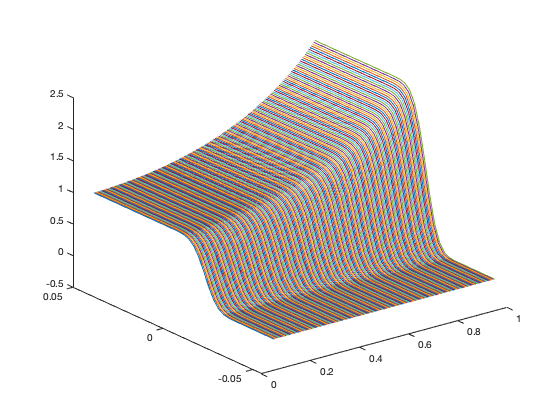

X_idx =     1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552
    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524 

Y_idx =     0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462    0.2513    0.2563    0.2613    0.2663    0.2714    0.2764    0.2814    0.2864    0.2915    0.2965
    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106    0.1156    0.1206    0.1256    0.1307    0.1357    0.1407    0.1457    0.1508    0.1558    0.1608    0.1658    0.1709    0.1759    0.1809    0.1859    0.1910    0.1960    0.2010    0.2060    0.2111    0.2161    0.2211    0.2261    0.2312    0.2362    0.2412    0.2462    0.2513    0.2563    0.2613    0.2663    0.2714    0.2764    0.2814    0.2864    0.2915 

S_fcont =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.000

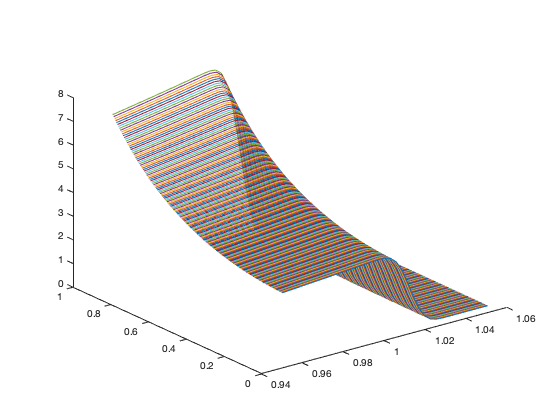

X_idx =     0.9497    0.9447    0.9397    0.9347    0.9296    0.9246    0.9196    0.9146    0.9095    0.9045    0.8995    0.8945    0.8894    0.8844    0.8794    0.8744    0.8693    0.8643    0.8593    0.8543    0.8492    0.8442    0.8392    0.8342    0.8291    0.8241    0.8191    0.8141    0.8090    0.8040    0.7990    0.7940    0.7889    0.7839    0.7789    0.7739    0.7688    0.7638    0.7588    0.7538    0.7487    0.7437    0.7387    0.7337    0.7286    0.7236    0.7186    0.7136    0.7085    0.7035
    0.9497    0.9447    0.9397    0.9347    0.9296    0.9246    0.9196    0.9146    0.9095    0.9045    0.8995    0.8945    0.8894    0.8844    0.8794    0.8744    0.8693    0.8643    0.8593    0.8543    0.8492    0.8442    0.8392    0.8342    0.8291    0.8241    0.8191    0.8141    0.8090    0.8040    0.7990    0.7940    0.7889    0.7839    0.7789    0.7739    0.7688    0.7638    0.7588    0.7538    0.7487    0.7437    0.7387    0.7337    0.7286    0.7236    0.7186    0.7136    0.7085 

Y_idx =     1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552    1.0552
    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524    1.0524 

S_fcont =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.000

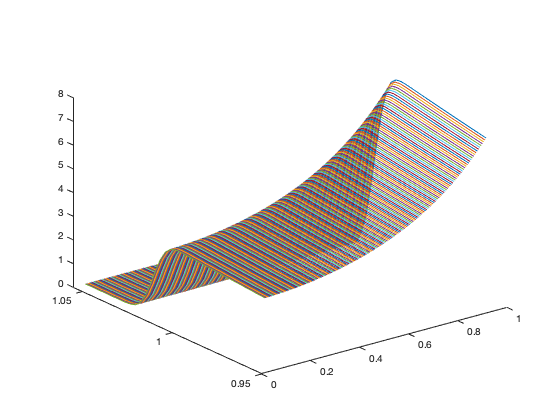

X_idx =    -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552   -0.0552
   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524   -0.0524 

Y_idx =     0.9497    0.9447    0.9397    0.9347    0.9296    0.9246    0.9196    0.9146    0.9095    0.9045    0.8995    0.8945    0.8894    0.8844    0.8794    0.8744    0.8693    0.8643    0.8593    0.8543    0.8492    0.8442    0.8392    0.8342    0.8291    0.8241    0.8191    0.8141    0.8090    0.8040    0.7990    0.7940    0.7889    0.7839    0.7789    0.7739    0.7688    0.7638    0.7588    0.7538    0.7487    0.7437    0.7387    0.7337    0.7286    0.7236    0.7186    0.7136    0.7085    0.7035
    0.9497    0.9447    0.9397    0.9347    0.9296    0.9246    0.9196    0.9146    0.9095    0.9045    0.8995    0.8945    0.8894    0.8844    0.8794    0.8744    0.8693    0.8643    0.8593    0.8543    0.8492    0.8442    0.8392    0.8342    0.8291    0.8241    0.8191    0.8141    0.8090    0.8040    0.7990    0.7940    0.7889    0.7839    0.7789    0.7739    0.7688    0.7638    0.7588    0.7538    0.7487    0.7437    0.7387    0.7337    0.7286    0.7236    0.7186    0.7136    0.7085 

S_fcont =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.000

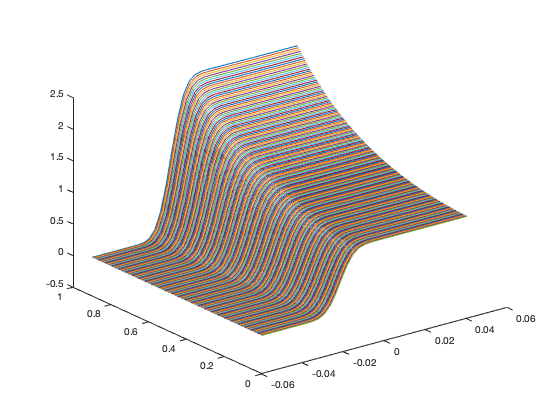


% bounding box for continued function
D_mesh_FC = -C*h:h:1+C*h;
[X_FC, Y_FC] = meshgrid(D_mesh_FC);

% paramterization of boundary
n_theta = (n-1)*4+1; % number of grid points on boundary
h_theta = 2*pi/(n_theta-1); % step size of boundary wrt theta

theta = transpose(linspace(0, 2*pi, n_theta)); % +1 because we include 2pi
Gamma = square_parameterization(theta); % boundary values that correspond to uniform theta mesh, but also the grid 


% partition bounds wrt to theta index
corner_theta = [0, pi/2, pi, 3*pi/2] / h_theta + 1; % indexes of corners of square wrt theta
S_patch_bounds = theta([corner_theta+10; corner_theta(2:end)-10, n_theta-10]); % partitions bounds wrt to theta for S type
C2_patch_bounds = theta([n_theta-20, corner_theta(2:end)-20; corner_theta(1:end); corner_theta + 20]); % partitions bounds wrt to theta for C1 type


% getting patches of S type partitions
fcont = zeros(C, n_theta);
for i = 1:size(S_patch_bounds, 2)
    patch_bounds = S_patch_bounds(:,i);
    patch_eta_n = round((patch_bounds(2) - patch_bounds(1)) / h_theta + 1);
    
    % returns x and y grids of patch, and has boundary on top of matrix
    M_S = construct_S_patch_parameterization(patch_bounds, d, h); % can only handle scalar eta and nu
    
    % can this be vectorized?
    eta_mesh = linspace(0, 1, patch_eta_n);
    nu_mesh = linspace(-C*(d-1)*h, 1, C+d); % extended mesh
    S_patch = zeros(d, patch_eta_n);
    X_idx = zeros(d+C, patch_eta_n);
    Y_idx = zeros(d, patch_eta_n);
    
    for nu_i = 1:(C+d)
        for eta_i = 1:patch_eta_n 
            omega_domain_value = M_S(eta_mesh(eta_i), nu_mesh(nu_i)); % coordinate vector in original domain
 
            if nu_i <= d
                S_patch(nu_i, eta_i) = f(omega_domain_value(1), omega_domain_value(2));
            end
            
            X_idx(nu_i, eta_i) = omega_domain_value(1);
            Y_idx(nu_i, eta_i) = omega_domain_value(2);
        end
    end
    S_fcont = fcont_gram_blend_S(S_patch, d, A, Q);
    
    figure;
    X_idx
    Y_idx
    S_fcont
    plot3(X_idx, Y_idx, S_fcont)
end

% gets x y coordinates given theta
function q = square_parameterization(theta)
    mod_theta = mod(theta, 2*pi);
    % we break the square into 4 segments
    msk1 = 0 <= mod_theta & mod_theta < pi/2;
    msk2 = pi/2 <= mod_theta & mod_theta < pi;
    msk3 = pi <= mod_theta & mod_theta < 3*pi/2;
    msk4 = 3*pi/2 <= mod_theta & mod_theta < 2*pi;
    
    q = zeros(length(mod_theta), 2);
    q(msk1, :) = [mod_theta(msk1)/(pi/2), zeros(sum(msk1), 1)];
    q(msk2, :) = [ones(sum(msk2), 1), mod_theta(msk2)/(pi/2)-1];
    q(msk3, :) = [3-mod_theta(msk3)/(pi/2), ones(sum(msk3), 1)];
    q(msk4, :) = [zeros(sum(msk4), 1), 4-mod_theta(msk4)/(pi/2)];
end

% gets unit normal given vector theta
function n = unit_normal(theta)
    mod_theta = mod(theta, 2*pi);
    % we break the square into 4 segments
    msk1 = 0 <= mod_theta & mod_theta < pi/2;
    msk2 = pi/2 <= mod_theta & mod_theta < pi;
    msk3 = pi <= mod_theta & mod_theta < 3*pi/2;
    msk4 = 3*pi/2 <= mod_theta & mod_theta < 2*pi;
    
    n = zeros(length(mod_theta), 2);
    n(msk1, :) = [zeros(sum(msk1), 1), -1*ones(sum(msk1), 1)];
    n(msk2, :) = [ones(sum(msk2), 1), zeros(sum(msk2), 1)];
    n(msk3, :) = [zeros(sum(msk3), 1), ones(sum(msk3), 1)];
    n(msk4, :) = [-1*ones(sum(msk4), 1), zeros(sum(msk4), 1)];
end

% constructs patches given the partition bounds (in theta space), d (number
% of inward points needed), h_theta (step size of theta), h (step size of
% cartesian mesh), f_xy (matrix of function values), should also return H
function [M_S] = construct_S_patch_parameterization(patch_bounds, d, h)
    % theta_min and theta_max
    theta_max = patch_bounds(2);
    theta_min = patch_bounds(1);
    
    % l_A is a function mapping the interval [0, 1] to theta values. Note a
    % l_A preserves the uniform mesh
    l_A = @(eta) eta*(theta_max-theta_min) + theta_min;
    M_S = @(eta, nu) square_parameterization(l_A(eta)) - nu*(d-1)*h*unit_normal(l_A(eta));
end